% The code below sets the properties of the communication channel.
ch = Channel;
% Assuming the measurements of the transmitter and receiver
% waveforms are synchronized, i.e. made at the same time.
ch.type = "sync";
% distance from transmitter to receiver
ch.distance = 10; 

 % define step-like waveform to send over channel
tx_wave = [zeros(1,150) ones(1,250)];

% send over the channel defined above
rx_wave=txrx(ch,tx_wave);

% % % Adjust the following parameters by adjusting the sliders % % %
c = 0.2301;
d = 151;
k = 0.5989;
a = 0.93;
 

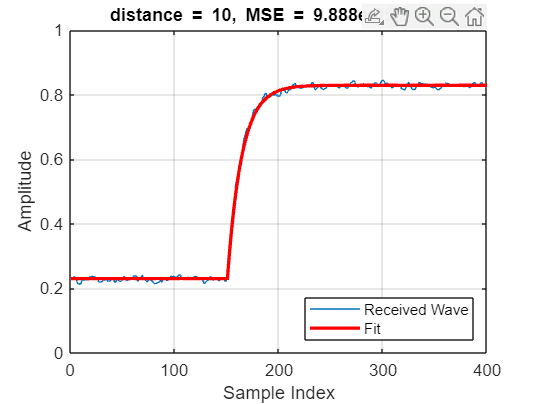

mse = fit_rcv(rx_wave,c,d,k,a); % fit channel output to model
add_title(ch.distance,mse);

function add_title(dist,mse)

ttl_string = ['distance = ' num2str(dist) ', MSE = ' num2str(mse,"%.3e")];
if mse < 1e-4
    ttl_string = [ttl_string '{\color{green} (OK!)}'];
else
    ttl_string = [ttl_string '{\color{red} (Too big)}'];
end
title(ttl_string); % put title on graph

end